# Kinect Camera Point Cloud Processing

David Olson, 13 Sep 2021

% Start Fresh
close all
clear all
clc

% Add Function Folders
addpath("User_Functions")

## Load Desired Data Set

% Load Data
load("Hardware_Data_Sets\SBT_CCW.mat")

% Clear Unused Variables
clear accel dt Fs gyro odo t

% Establish Point Cloud Processing Parameters
[~, K, num_frames] = size(xyz);

% Convert 3D Matrix into Cell Array
new_xyz = cell(num_frames,1);
for n = 1 : num_frames
    new_xyz{n} = xyz(:,:,n);
end
xyz = new_xyz;

## Separate Point Cloud Data into Wall and Floor Points

% Define Thresholds
x_thres = 1.5;
z_thres = 0;

% Separate Points
xyz_wall = cell(num_frames,1);
xyz_floor = cell(num_frames,1);

for n = 1 : num_frames
    
    % Remove all {0;0;0] measurements
    zero_mask = logical(sum(xyz{n}) ~= 0);
    xyz{n} = xyz{n}(:,zero_mask);
    
    % Locate and Store floor points
    floor_mask = (xyz{n}(1,:) < x_thres) & (xyz{n}(3,:) < z_thres);
    xyz_floor{n} = xyz{n}(:,floor_mask);
    
    % Locate and Store wall points
    wall_mask = (xyz{n}(3,:) >= z_thres);
    xyz_wall{n} = xyz{n}(:,wall_mask);
    
end

% - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - -
% Test Thresholding
test_point_cloud_flag = false;

if (test_point_cloud_flag == true)
    test_frame = 22;
    plot_point_cloud(xyz{test_frame}, ['Full Point Cloud at t = ', num2str(test_frame), 's'])
    plot_point_cloud(xyz_wall{test_frame}, ['Wall Only Point Cloud at t = ', num2str(test_frame), 's'])
    plot_point_cloud(xyz_floor{test_frame}, ['Floor Only Point Cloud at t = ', num2str(test_frame), 's'])
end

## Shift Wall and Floor Point Clouds to the Origin

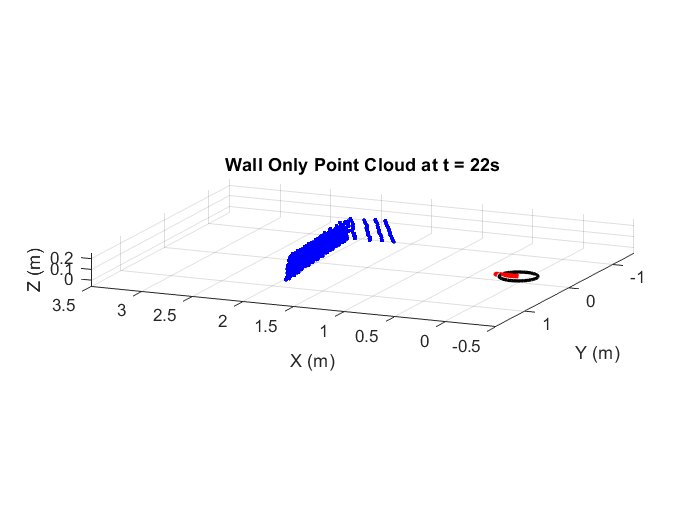

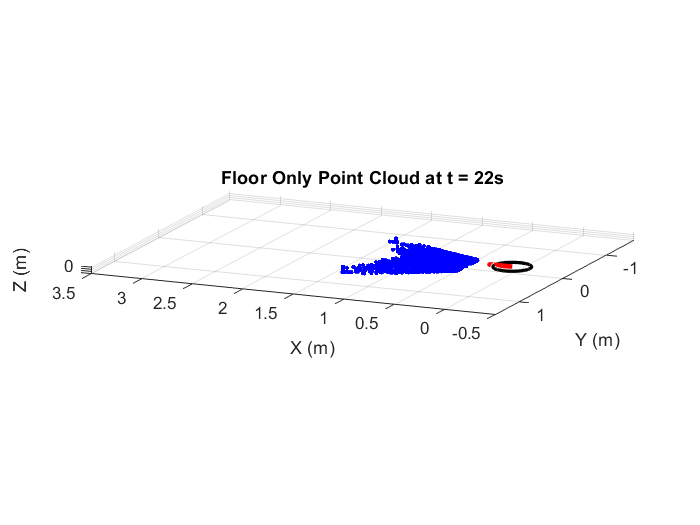

% % Locate and Shift each floor point cloud to the origin
% for n = 1 : num_frames
%     x_avg = mean(xyz_floor{n}(1,:));
%     y_avg = mean(xyz_floor{n}(2,:));
%     xyz_floor{n} = xyz_floor{n} - [x_avg; y_avg; 0];
% end

% % Locate and Shift each wall point cloud to the origin
% for n = 1 : num_frames
%     x_avg = mean(xyz_wall{n}(1,:));
%     xyz_wall{n} = xyz_wall{n} - [x_avg; 0; 0];
% end

% - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - -
% Test Point Cloud Shifting
test_point_cloud_flag = true;

if (test_point_cloud_flag == true)
    test_frame = 22;
    plot_point_cloud(xyz_wall{test_frame}, ['Wall Only Point Cloud at t = ', num2str(test_frame), 's'])
    hold on
    plot_point_cloud(xyz_floor{test_frame}, ['Floor Only Point Cloud at t = ', num2str(test_frame), 's'])
    quiver3(0,0,0,cos(3*pi/180),0,sin(3*pi/180))
    hold off
end

## Complete the SNHT Floor Search

Searching for pitch only!

Begin Processing Frame #2

Elapsed time is 3.703700 seconds.


Begin Processing Frame #3

Elapsed time is 3.621131 seconds.


Begin Processing Frame #4

Elapsed time is 3.627818 seconds.


Begin Processing Frame #5

Elapsed time is 3.634654 seconds.


Begin Processing Frame #6

Elapsed time is 3.507152 seconds.


Begin Processing Frame #7

Elapsed time is 3.574359 seconds.


Begin Processing Frame #8

Elapsed time is 3.523016 seconds.


Begin Processing Frame #9

Elapsed time is 3.584881 seconds.


Begin Processing Frame #10

Elapsed time is 3.548580 seconds.


Begin Processing Frame #11

Elapsed time is 3.624727 seconds.


Begin Processing Frame #12

Elapsed time is 3.600805 seconds.


Begin Processing Frame #13

Elapsed time is 3.635822 seconds.


Begin Processing Frame #14

Elapsed time is 3.664417 seconds.


Begin Processing Frame #15

Elapsed time is 3.707795 seconds.


Begin Processing Frame #16

Elapsed time is 3.652250 seconds.


Begin Processing Frame #17

Elapsed time is 3.641240 seconds.


Begin Processing Frame #18

Elapsed time is 3.710308 seconds.


Begin Processing Frame #19

Elapsed time is 3.699284 seconds.


Begin Processing Frame #20

Elapsed time is 3.712908 seconds.


Begin Processing Frame #21

Elapsed time is 3.868833 seconds.


Begin Processing Frame #22

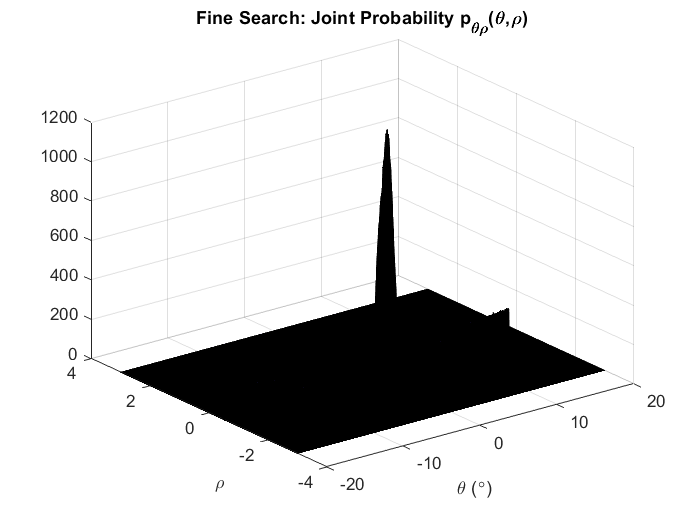

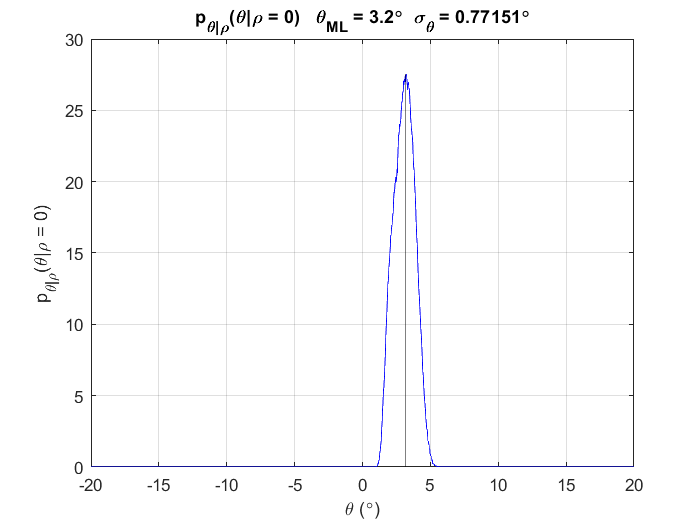

Elapsed time is 4.041921 seconds.


Begin Processing Frame #23

Elapsed time is 3.680347 seconds.


Begin Processing Frame #24

Elapsed time is 3.847936 seconds.


Begin Processing Frame #25

Elapsed time is 3.533413 seconds.


Begin Processing Frame #26

Elapsed time is 3.325879 seconds.


Begin Processing Frame #27

Elapsed time is 3.487885 seconds.


Begin Processing Frame #28

Elapsed time is 3.934740 seconds.


Begin Processing Frame #29

Elapsed time is 3.788982 seconds.


Begin Processing Frame #30

Elapsed time is 3.860388 seconds.


Begin Processing Frame #31

Elapsed time is 3.806326 seconds.


Begin Processing Frame #32

Elapsed time is 3.838587 seconds.


Begin Processing Frame #33

Elapsed time is 3.745349 seconds.


Begin Processing Frame #34

Elapsed time is 3.789577 seconds.


Begin Processing Frame #35

Elapsed time is 3.791444 seconds.


Begin Processing Frame #36

Elapsed time is 3.787155 seconds.


Begin Processing Frame #37

Elapsed time is 3.776599 seconds.


Begin Processing Frame #38

Elapsed time is 3.748625 seconds.


Begin Processing Frame #39

Elapsed time is 3.605410 seconds.


Begin Processing Frame #40

Elapsed time is 3.583720 seconds.


Begin Processing Frame #41

Elapsed time is 3.812347 seconds.


Begin Processing Frame #42

Elapsed time is 3.337529 seconds.


Begin Processing Frame #43

Elapsed time is 2.931022 seconds.


Begin Processing Frame #44

Elapsed time is 3.239693 seconds.


Begin Processing Frame #45

Elapsed time is 3.799997 seconds.


Begin Processing Frame #46

Elapsed time is 3.653357 seconds.


Begin Processing Frame #47

Elapsed time is 3.652593 seconds.


Begin Processing Frame #48

Elapsed time is 3.687745 seconds.


Begin Processing Frame #49

Elapsed time is 3.712124 seconds.


Begin Processing Frame #50

Elapsed time is 3.663958 seconds.


Begin Processing Frame #51

Elapsed time is 3.784049 seconds.


Begin Processing Frame #52

Elapsed time is 3.729945 seconds.


Begin Processing Frame #53

Elapsed time is 3.692455 seconds.


Begin Processing Frame #54

Elapsed time is 3.618000 seconds.


Begin Processing Frame #55

Elapsed time is 3.780466 seconds.


Begin Processing Frame #56

Elapsed time is 3.891515 seconds.


Begin Processing Frame #57

Elapsed time is 3.705445 seconds.


Begin Processing Frame #58

Elapsed time is 3.798504 seconds.


Begin Processing Frame #59

Elapsed time is 3.839894 seconds.


Begin Processing Frame #60

Elapsed time is 3.389233 seconds.


Begin Processing Frame #61

Elapsed time is 3.243975 seconds.


Begin Processing Frame #62

Elapsed time is 3.688316 seconds.


Begin Processing Frame #63

Elapsed time is 3.786019 seconds.


Begin Processing Frame #64

Elapsed time is 3.615074 seconds.


Begin Processing Frame #65

Elapsed time is 3.704238 seconds.


Begin Processing Frame #66

Elapsed time is 3.780523 seconds.


Begin Processing Frame #67

Elapsed time is 3.797864 seconds.


Begin Processing Frame #68

Elapsed time is 3.813139 seconds.


Begin Processing Frame #69

Elapsed time is 3.636707 seconds.


Begin Processing Frame #70

Elapsed time is 3.754107 seconds.


Begin Processing Frame #71

Elapsed time is 3.665123 seconds.


Begin Processing Frame #72

Elapsed time is 3.683351 seconds.


Begin Processing Frame #73

Elapsed time is 3.511693 seconds.


Begin Processing Frame #74

Elapsed time is 3.875116 seconds.


Begin Processing Frame #75

Elapsed time is 3.381335 seconds.


Begin Processing Frame #76

Elapsed time is 3.162889 seconds.


Begin Processing Frame #77

Elapsed time is 3.460121 seconds.


Begin Processing Frame #78

Elapsed time is 3.755203 seconds.


Begin Processing Frame #79

Elapsed time is 3.787724 seconds.


Begin Processing Frame #80

Elapsed time is 3.645312 seconds.


Begin Processing Frame #81

Elapsed time is 3.648732 seconds.


Begin Processing Frame #82

Elapsed time is 3.669943 seconds.


Begin Processing Frame #83

Elapsed time is 3.663088 seconds.


Begin Processing Frame #84

Elapsed time is 3.688928 seconds.


Begin Processing Frame #85

Elapsed time is 3.646904 seconds.


Begin Processing Frame #86

Elapsed time is 3.603632 seconds.


Begin Processing Frame #87

Elapsed time is 3.642326 seconds.


Begin Processing Frame #88

Elapsed time is 3.592830 seconds.


Begin Processing Frame #89

Elapsed time is 3.591256 seconds.


Begin Processing Frame #90

Elapsed time is 3.743780 seconds.


Begin Processing Frame #91

Elapsed time is 3.808309 seconds.


Total SNHT Pitch Processing Time


Elapsed time is 3.816900 seconds.


% Pre-Allocate Memory
theta_meas = zeros(1,91);
theta_sigmas = zeros(1,91);

% Run SNHT pitch algorithm
test_frame = 22;
for n = 2 : num_frames
    
    % Select Test Frame to Plot
    if (n == test_frame)
        plot_flag = true;
    else
        plot_flag = false;
    end
    
    % Run SNHT Pitch
    fprintf(['Begin Processing Frame #', num2str(n)])
    tic 
    [theta_meas(n), theta_sigmas(n)] = SNHT_pitch(xyz_floor{n}, plot_flag);
    toc
    
end

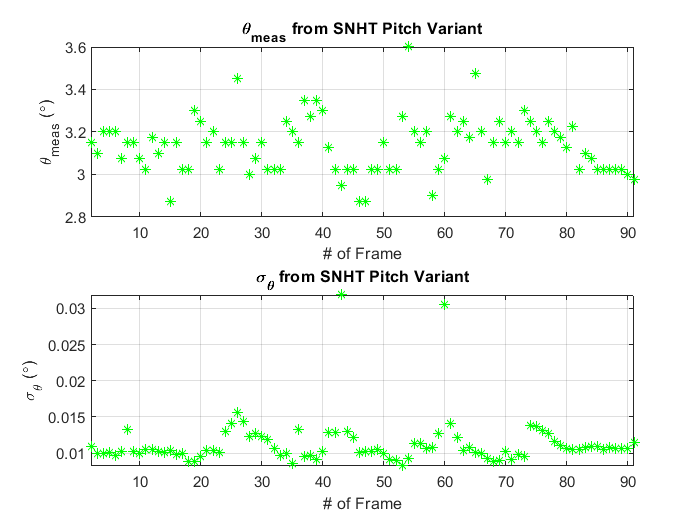

% Plot Results
figure
subplot(2,1,1)
plot(1:num_frames, theta_meas * 180/pi, 'g*')
title('\theta_m_e_a_s from SNHT Pitch Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\theta_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, theta_sigmas * 180/pi, 'g*')
title('\sigma_\theta from SNHT Pitch Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\theta (\circ)')
grid on

## Process Wall Point Clouds

Begin Processing Frame #2

Elapsed time is 0.290338 seconds.


Begin Processing Frame #3

Elapsed time is 0.266660 seconds.


Begin Processing Frame #4

Elapsed time is 0.261541 seconds.


Begin Processing Frame #5

Elapsed time is 0.260528 seconds.


Begin Processing Frame #6

Elapsed time is 0.276350 seconds.


Begin Processing Frame #7

Elapsed time is 0.263225 seconds.


Begin Processing Frame #8

Elapsed time is 0.260038 seconds.


Begin Processing Frame #9

Elapsed time is 0.255539 seconds.


Begin Processing Frame #10

Elapsed time is 0.257920 seconds.


Begin Processing Frame #11

Elapsed time is 0.255283 seconds.


Begin Processing Frame #12

Elapsed time is 0.260311 seconds.


Begin Processing Frame #13

Elapsed time is 0.254866 seconds.


Begin Processing Frame #14

Elapsed time is 0.257541 seconds.


Begin Processing Frame #15

Elapsed time is 0.260257 seconds.


Begin Processing Frame #16

Elapsed time is 0.287728 seconds.


Begin Processing Frame #17

Elapsed time is 0.307351 seconds.


Begin Processing Frame #18

Elapsed time is 0.675791 seconds.


Begin Processing Frame #19

Elapsed time is 0.730845 seconds.


Begin Processing Frame #20

Elapsed time is 0.757348 seconds.


Begin Processing Frame #21

Elapsed time is 0.974564 seconds.


Begin Processing Frame #22

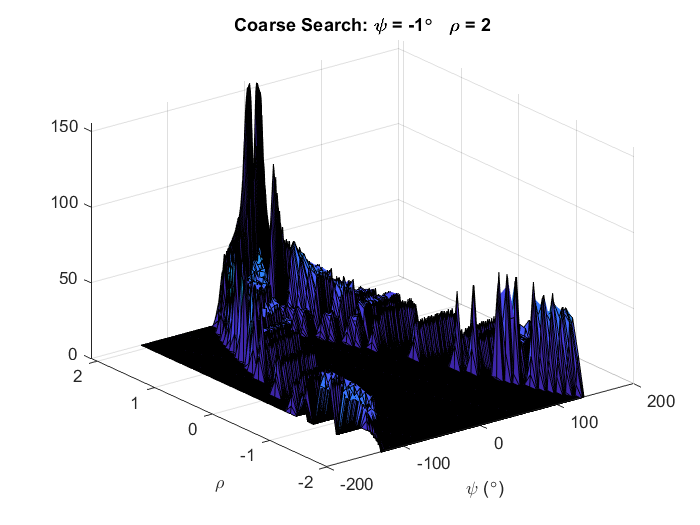

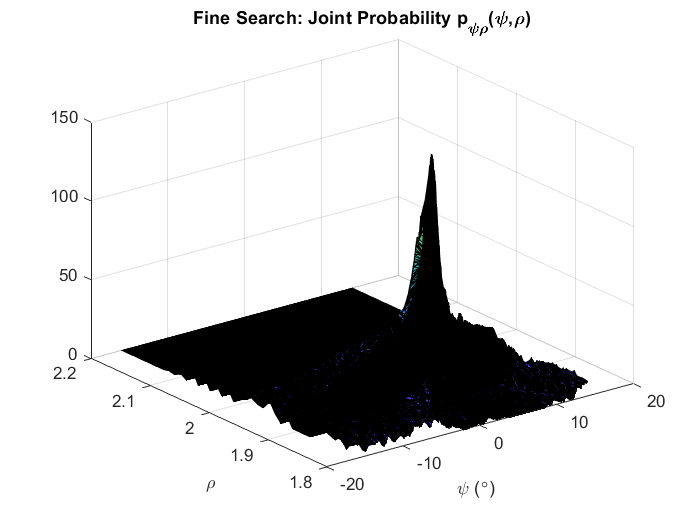

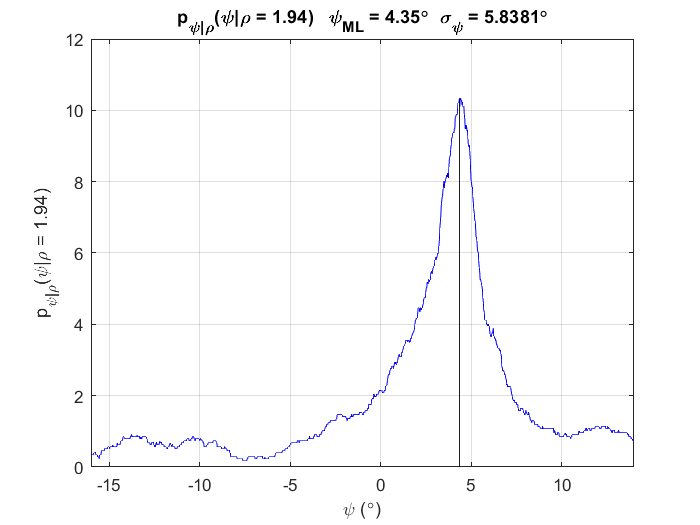

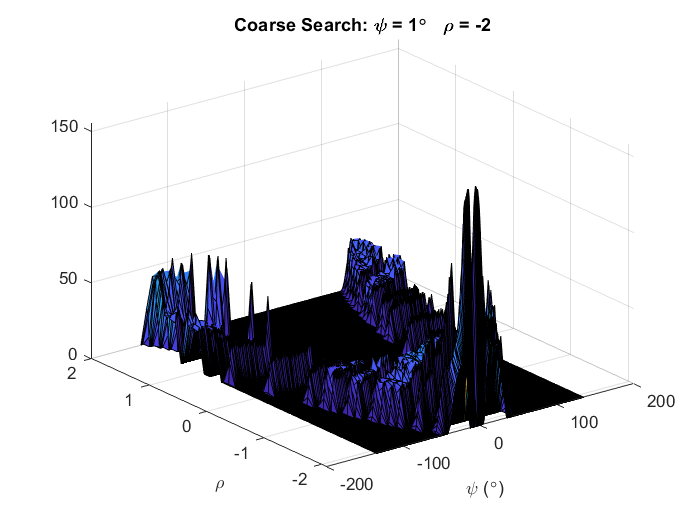

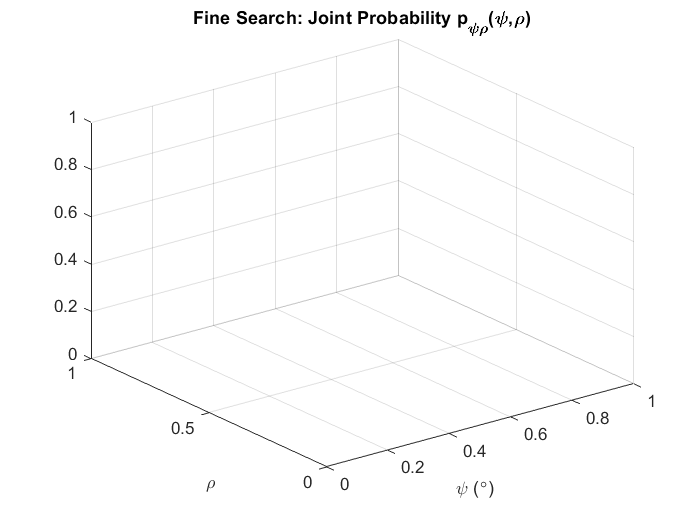

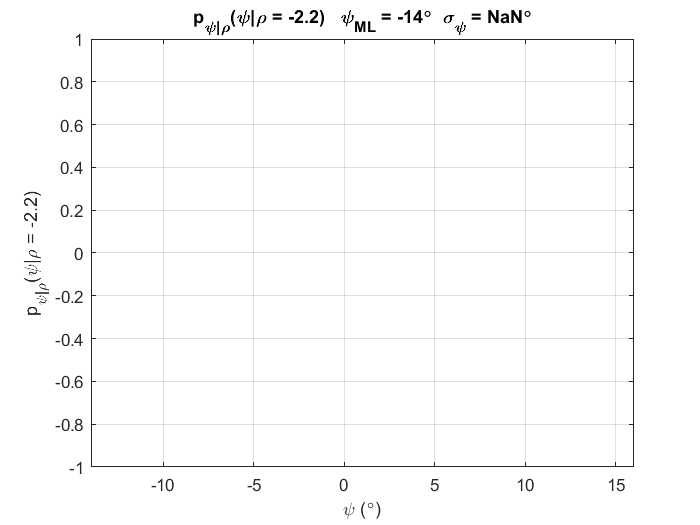

Elapsed time is 1.325187 seconds.


Begin Processing Frame #23

Elapsed time is 0.973372 seconds.


Begin Processing Frame #24

Elapsed time is 1.142948 seconds.


Begin Processing Frame #25

Elapsed time is 1.456428 seconds.


Begin Processing Frame #26

Elapsed time is 1.660388 seconds.


Begin Processing Frame #27

Elapsed time is 1.640667 seconds.


Begin Processing Frame #28

Elapsed time is 0.615750 seconds.


Begin Processing Frame #29

Elapsed time is 0.208164 seconds.


Begin Processing Frame #30

Elapsed time is 0.195975 seconds.


Begin Processing Frame #31

Elapsed time is 0.195698 seconds.


Begin Processing Frame #32

Elapsed time is 0.215202 seconds.


Begin Processing Frame #33

Elapsed time is 0.215883 seconds.


Begin Processing Frame #34

Elapsed time is 0.222538 seconds.


Begin Processing Frame #35

Elapsed time is 0.644688 seconds.


Begin Processing Frame #36

Elapsed time is 0.673630 seconds.


Begin Processing Frame #37

Elapsed time is 0.741952 seconds.


Begin Processing Frame #38

Elapsed time is 0.812841 seconds.


Begin Processing Frame #39

Elapsed time is 0.876366 seconds.


Begin Processing Frame #40

Elapsed time is 0.939947 seconds.


Begin Processing Frame #41

Elapsed time is 1.143473 seconds.


Begin Processing Frame #42

Elapsed time is 1.474545 seconds.


Begin Processing Frame #43

Elapsed time is 1.669409 seconds.


Begin Processing Frame #44

Elapsed time is 1.623777 seconds.


Begin Processing Frame #45

Elapsed time is 1.186206 seconds.


Begin Processing Frame #46

Elapsed time is 0.305063 seconds.


Begin Processing Frame #47

Elapsed time is 0.299422 seconds.


Begin Processing Frame #48

Elapsed time is 0.299574 seconds.


Begin Processing Frame #49

Elapsed time is 0.193255 seconds.


Begin Processing Frame #50

Elapsed time is 0.213120 seconds.


Begin Processing Frame #51

Elapsed time is 0.214996 seconds.


Begin Processing Frame #52

Elapsed time is 0.583585 seconds.


Begin Processing Frame #53

Elapsed time is 0.654585 seconds.


Begin Processing Frame #54

Elapsed time is 0.741538 seconds.


Begin Processing Frame #55

Elapsed time is 0.726035 seconds.


Begin Processing Frame #56

Elapsed time is 0.932133 seconds.


Begin Processing Frame #57

Elapsed time is 0.873271 seconds.


Begin Processing Frame #58

Elapsed time is 1.001539 seconds.


Begin Processing Frame #59

Elapsed time is 1.402739 seconds.


Begin Processing Frame #60

Elapsed time is 1.680661 seconds.


Begin Processing Frame #61

Elapsed time is 1.811141 seconds.


Begin Processing Frame #62

Elapsed time is 1.329088 seconds.


Begin Processing Frame #63

Elapsed time is 0.208054 seconds.


Begin Processing Frame #64

Elapsed time is 0.217253 seconds.


Begin Processing Frame #65

Elapsed time is 0.223327 seconds.


Begin Processing Frame #66

Elapsed time is 0.221624 seconds.


Begin Processing Frame #67

Elapsed time is 0.405782 seconds.


Begin Processing Frame #68

Elapsed time is 0.659647 seconds.


Begin Processing Frame #69

Elapsed time is 0.653915 seconds.


Begin Processing Frame #70

Elapsed time is 0.780224 seconds.


Begin Processing Frame #71

Elapsed time is 0.893180 seconds.


Begin Processing Frame #72

Elapsed time is 0.855212 seconds.


Begin Processing Frame #73

Elapsed time is 1.047241 seconds.


Begin Processing Frame #74

Elapsed time is 1.176583 seconds.


Begin Processing Frame #75

Elapsed time is 1.622111 seconds.


Begin Processing Frame #76

Elapsed time is 1.696818 seconds.


Begin Processing Frame #77

Elapsed time is 1.830264 seconds.


Begin Processing Frame #78

Elapsed time is 0.643889 seconds.


Begin Processing Frame #79

Elapsed time is 0.162398 seconds.


Begin Processing Frame #80

Elapsed time is 0.159944 seconds.


Begin Processing Frame #81

Elapsed time is 0.165142 seconds.


Begin Processing Frame #82

Elapsed time is 0.164287 seconds.


Begin Processing Frame #83

Elapsed time is 0.158331 seconds.


Begin Processing Frame #84

Elapsed time is 0.163687 seconds.


Begin Processing Frame #85

Elapsed time is 0.164584 seconds.


Begin Processing Frame #86

Elapsed time is 0.160189 seconds.


Begin Processing Frame #87

Elapsed time is 0.158749 seconds.


Begin Processing Frame #88

Elapsed time is 0.160686 seconds.


Begin Processing Frame #89

Elapsed time is 0.161932 seconds.


Begin Processing Frame #90

Elapsed time is 0.161164 seconds.


Begin Processing Frame #91

Elapsed time is 0.165394 seconds.


% Pre-Allocate Memory
psi_fw_meas = zeros(1,91);
psi_fw_sigmas = zeros(1,91);
psi_sw_meas = zeros(1,91);
psi_sw_sigmas = zeros(1,91);

% Run SNHT pitch algorithm
test_frame = 22;
for n = 2 : num_frames
    
    % Select Test Frame to Plot
    if (n == test_frame)
        plot_flag = true;
    else
        plot_flag = false;
    end
    
    % Run SNHT Pitch
    fprintf(['Begin Processing Frame #', num2str(n)])
    tic 
    [psi_fw_meas(n), psi_fw_sigmas(n)] = SNHT_front_wall(xyz_wall{n}, plot_flag);
    [psi_sw_meas(n), psi_sw_sigmas(n)] = SNHT_side_wall(xyz_wall{n}, plot_flag);
    toc
    
end

% Plot Results
figure
subplot(2,1,1)
plot(1:num_frames, psi_fw_meas * 180/pi, 'b*')
title('\psi_m_e_a_s from SNHT Front Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\psi_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, psi_fw_sigmas * 180/pi, 'b*')
title('\sigma_\psi from SNHT Front Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\psi (\circ)')
grid on

figure
subplot(2,1,1)
plot(1:num_frames, psi_sw_meas * 180/pi, 'b*')
title('\psi_m_e_a_s from SNHT Side Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\psi_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, psi_sw_sigmas * 180/pi, 'b*')
title('\sigma_\psi from SNHT Side Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\psi (\circ)')
grid on